# Glenoid Processing Tests using GIBBON

## Starting Notes

This code uses the right scapula and humerus extracted from the Visible Human CT dataset to trial processing steps for FE analysis with a focus on using the GIBBON toolbox. The scapula and humerus meshes were exported from the Materialise suite of software as ASCII STL's in their original coordinate system (scapula.stl and humerus.stl). The only processing performed on these meshes was to uniformly mesh them to have a target triangle edge length of 1mm. This means they still aren't necessraily too smooth and could do with some extra processing or better masking.

There are also a number of additional objects exported that fit these meshes:

- **deepGlenoidCentre.txt:** includes the 3D coordinate of the estimated deepest point at the centre of the glenoid. This should serve as the origin for the scapula coordinate system.

- **glenoidPlanes.xml:** contains the planes fitted around the glenoid surface and glenoid axes. These planes represent the XY, XZ and YZ planes of the glenoid surface, with: (i) the Z axes being the normal away from a plane fitted to the glenoid surface; (ii) the Y axes being parralel to a line made by the supraglenoid and infraglenoid tubercle; and (iii) the X axes being the cross product of these remaining axes, respresenting the anterior-posterio aspect of the glenoid.

- **glenoidRimPoints.txt:** includes the 3D coordinates of a number of points estimated to fall on the glenoid rim. These are mainly estimated from the coronal plane slices of the CT, whereby the closest points/edges to the humerus are selected. They may not fit exactly on the glenoid mesh due to the potential small amount of smoothing done in uniformly remeshing.

- **humeralHeadSphere.txt:** includes the 3D coordinates of the centre and the radius measurement of a sphere fitted to the humeral head mesh.

This code includes a focus on generating cartilage on the surfaces of these structures, using slicing and extending features recently added to GIBBON toolbox, as per the Github issues #62 ([https://github.com/gibbonCode/GIBBON/issues/62](https://github.com/gibbonCode/GIBBON/issues/62)) and #63 ([https://github.com/gibbonCode/GIBBON/issues/63](https://github.com/gibbonCode/GIBBON/issues/63)).

Settings for script

warning off
fontSize = 25;

## Import STL's

Load and visualise STL files

%Load STLs
scapulaSTL = import_STL('scapula.stl');
humerusSTL = import_STL('humerus.stl');

%Extract the faces and vertices
scapulaF = scapulaSTL.solidFaces{1};
scapulaV = scapulaSTL.solidVertices{1};
humerusF = humerusSTL.solidFaces{1};
humerusV = humerusSTL.solidVertices{1};

%Merge vertices
[scapulaF,scapulaV] = mergeVertices(scapulaF,scapulaV);
[humerusF,humerusV] = mergeVertices(humerusF,humerusV);

%Plot the models
cFigure;
title('Imported patch data from STL','fontSize',25);
gpatch(scapulaF,scapulaV,'g','k',1,1e-5);
hold on
gpatch(humerusF,humerusV,'r','k',1,1e-5);
axisGeom;
camlight('headlight');
lighting phong; axis off;

## Import Measurements Data

Import the associated measurements for the scapula and humerus meshes.

%Load the deep glenoid point text
%Read in with line delimiter
C = importdata('deepGlenoidCentre.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'deepGlenoid');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
landmarks.deepGlenoid(1) = str2double(rowSplit(2));
landmarks.deepGlenoid(2) = str2double(rowSplit(3));
landmarks.deepGlenoid(3) = str2double(rowSplit(4));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the glenoid rim points
%Read in with line delimiter
C = importdata('glenoidRimPoints.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'glenoidRim');
end
clear rr
%Extract the relevant row
rowTxt = C(rowInd,1);
%Loop through the number of points
for pp = 1:length(rowTxt)
    %Split the string by spaces
    rowSplit = strsplit(rowTxt{pp},' ');
    %The name is now in the first cell
    %The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
    landmarks.(char(rowSplit(1)))(1) = str2double(rowSplit(2));
    landmarks.(char(rowSplit(1)))(2) = str2double(rowSplit(3));
    landmarks.(char(rowSplit(1)))(3) = str2double(rowSplit(4));
    %Create a variable for the glenoid rim names
    glenoidRimLabels{pp} = (char(rowSplit(1)));
end
clear pp
%Cleanup
clear C rowInd rowTxt rowSplit

%Load the humeral head sphere text
%Read in with line delimiter
C = importdata('humeralHeadSphere.txt','\n');
%Identify the row with the point label
for rr = 1:length(C)
    rowInd(rr) = contains(C{rr,1},'humeralHead');
end
clear rr
%Extract the relevant row
rowTxt = C{rowInd,1};
%Split the string by spaces
rowSplit = strsplit(rowTxt,' ');
%The X,Y,Z coordinates are now in the 2nd, 3rd and 4th cells
%The radius size is now in the 5th cell
landmarks.humeralHeadCentre(1) = str2double(rowSplit(2));
landmarks.humeralHeadCentre(2) = str2double(rowSplit(3));
landmarks.humeralHeadCentre(3) = str2double(rowSplit(4));
landmarks.humeralHeadRadius(1) = str2double(rowSplit(5));
%Cleanup
clear C rowInd rowTxt rowSplit

%Load in the planes xml file
[tree, RootName, DOMnode] = xml_read('glenoidPlanes.xml');
%Extract the details
for pp = 1:3
    planes.(char(tree.Plane(pp).Name)).origin = tree.Plane(pp).Origin;
    planes.(char(tree.Plane(pp).Name)).normal = tree.Plane(pp).Normal;
    planes.(char(tree.Plane(pp).Name)).xAxis = tree.Plane(pp).X_DASH_axis;
    planes.(char(tree.Plane(pp).Name)).yAxis = tree.Plane(pp).Y_DASH_axis;
end
clear pp
%Cleanup
clear tree RootName DOMnode

## Align the Scapula Planes to the World

To make life easier with processing, the XY, YZ and XZ planes of the scapula can be aligned to the world coordinate system, with the origin being at the deep glenoid point. The following code rotates all elements that have been imported so that they all match up.

The following section uses the 'vrrotvec' and 'vrrotvec2mat' functions to align the glenoid coordinate system to the world coordinate system by matching up the world and scapula XY planes.

%Calculate the rotation between the glenoid plane vector and the worlds
%Z-axis vector
r = vrrotvec(planes.scapulaXYplane.normal,[0,0,1]);
%Get the rotation matrix for this alignment
m = vrrotvec2mat(r);

%Rotate and translate the points so they align at the origin and world XY
%axis. This also ensures that the other axes align with the other glenoid
%planes, however, they then need to be rotated 90 degrees around the Z-axis
%for these to align to the appropriate coordinate system.
%Set translation vector
transVec = (landmarks.deepGlenoid * m)
%Scapula vertices
scapulaV = (scapulaV * m) - transVec;
%Humerus vertices
humerusV = (humerusV * m) - transVec;
%Landmarks
fld = fieldnames(landmarks);
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * m) - transVec;
end
clear ff

%Do the final 90 dgeree rotation around the Z axis
%Scapula vertices
scapulaV = (scapulaV * rotz(-90));
%Humerus vertices
humerusV = (humerusV * rotz(-90));
%Landmarks
for ff = 1:length(fld)
    landmarks.(fld{ff}) = (landmarks.(fld{ff}) * rotz(-90));
end
clear ff fld

%Visualise rotated data
cFigure;
gpatch(scapulaF,scapulaV,'b','k',0.2,1e-5);
hold on
gpatch(humerusF,humerusV,'b','k',0.2,1e-5);
axisGeom;
quiverVec([0,0,0],vecnormalize([1,0,0]),25,'r');
quiverVec([0,0,0],vecnormalize([0,1,0]),25,'g');
quiverVec([0,0,0],vecnormalize([0,0,1]),25,'b');

%Cleanup
clear r m

## Slice Up the Scapula

Use GIBBON's slicing tool to extract the glenoid face from the rest of the scapula. This will be sliced at a point 30mm back from the deep glenoid point along the normal of the plane fit to the glenoid surface. Prior to this though, so slicing along the X and Y axis directions is required to ensure extra bits of the scapula aren't included in the glenoid face.

%Specify the snap tolerance
snapTolerance = mean(patchEdgeLengths(scapulaF,scapulaV))/100;

%Cut above the glenoid

%Create the cutting plane by a normal vector
n = vecnormalize([0 1 0]); %Normal direction to plane

%Specify the point on the plane (25mm above the glenoid centre)
P = [0,25,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF,scapulaV,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Remove the back side of the scapula

%Create the cutting plane by a normal vector
n = vecnormalize([-1 0 0]); %Normal direction to plane

%Specify the point on the plane (17mm back from the glenoid centre)
P = [-17,0,0];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Lastly, grab the actual glenoid surface.

%Create the cutting plane by a normal vector
n = vecnormalize([0 0 -1]); %Normal direction to plane

%Specify the point on the plane (30mm back from the glenoid face)
P = [0,0,-3];

%Slicing the surface (note 3rd color data output is supressed)
[scapulaF_slice,scapulaV_slice,~,logicSide,scapulaE_slice] = ...
    triSurfSlice(scapulaF_slice,scapulaV_slice,[],P,n,snapTolerance);

%Keep only part below the plane and clean up
[scapulaF_slice,scapulaV_slice,indFix] = patchCleanUnused(scapulaF_slice(logicSide,:),scapulaV_slice);
scapulaE_slice = indFix(scapulaE_slice);

Visualise the kept piece

%Visualise kept piece
cFigure; hold on;
hp1 = gpatch(scapulaF,scapulaV,'kw','none',0.25);
hp2 = gpatch(scapulaF_slice,scapulaV_slice,'rw','k',1);
gpatch(scapulaE_slice,scapulaV_slice,'none','b',1,3);
legend([hp1 hp2],{'Original','Cut surface'})
axisGeom; axis manual; camlight headligth;
colormap gjet;
set(gca,'FontSize',fontSize);

***TODO: There are likely some sharp triangle edges at the cuts that should be smoothed out. Also it will be necessray to add a backing surface to the cuts that can be used to fix as a boundary surface.***

## Visualise the Landmarks on the Sliced Glenoid

This next step simply provides a visualisation to check that all of the landmarks are appropriately positioned on the rotated and sliced glenoid.

%Set a new glenoid vairable to call easier
glenoidV = scapulaV_slice;
glenoidF = scapulaF_slice;
glenoidE = scapulaE_slice;

%Visualise the cut glenoid and its associated landmarks
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot deep glenoid landmark
scatter3(landmarks.deepGlenoid(1),...
    landmarks.deepGlenoid(2),...
    landmarks.deepGlenoid(3),100,'r','filled');
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end
clear gg

Note that the above landmarks for the glenoid rim don't naturally sit on the surface. There is therefore a need to identify the closest vertices to these for appropriate meshing of the cartilage.

## Identify Appropriate Glenoid Rim Points

As above, there is a need to identify where the closest vertices are to these glenoid rim points so that they match up on the surface. This can be done fairly easily by calculating the distance between all of the rim points to the vertices, and finding the minum one.

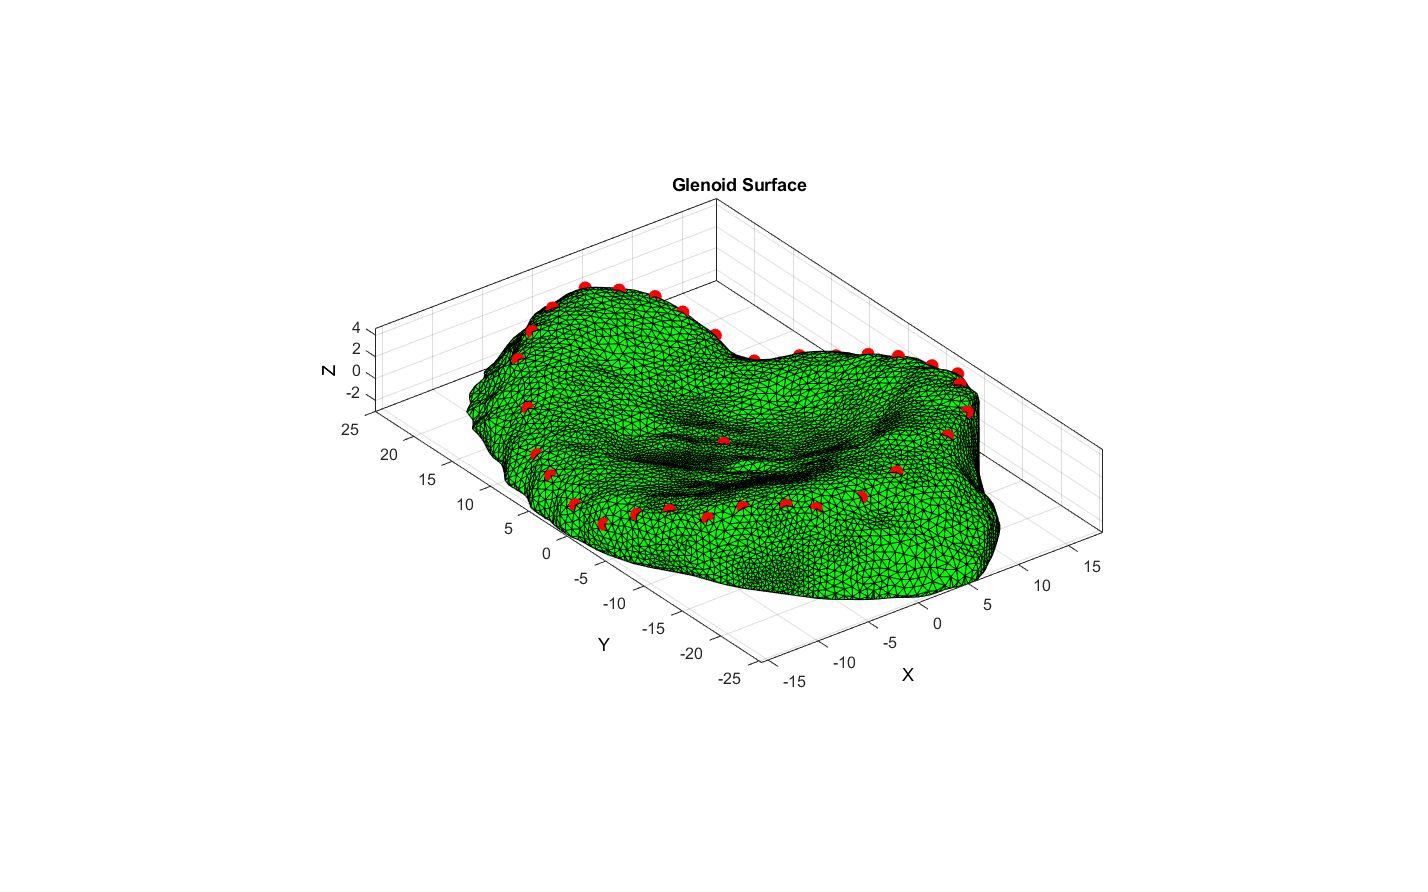

%Calculate nearest vertices to each glenoid rim point
for gg = 1:length(glenoidRimLabels)

    %Loop through glenoid vertices and calculate distances
    for vv = 1:length(glenoidV)
        %Specify points
        P1 = glenoidV(vv,:); P2 = landmarks.(glenoidRimLabels{gg})(1,:);
        distPoints(vv) = sqrt((P1(:,1)-P2(:,1)).^2+(P1(:,2)-P2(:,2)).^2+(P1(:,3)-P2(:,3)).^2);
        clear P1 P2
    end
    clear vv
    
    %Find the minimum distance
    minInd = find(distPoints == min(distPoints));
    
    %Replace the current glenoid rim point with the one from the glenoid
    %surface vertices
    landmarks.(glenoidRimLabels{gg})(1,:) = glenoidV(minInd,:);
    
    %Cleanup
    clear distPoints minInd

end
clear gg

%Visualise updated glenoid rim points on surface
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot deep glenoid landmark
scatter3(landmarks.deepGlenoid(1),...
    landmarks.deepGlenoid(2),...
    landmarks.deepGlenoid(3),100,'r','filled');
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end

These new points are OK, but the shape made by them could be smoother, so we can fit a nice smooth shape to these points and then match it back up to the glenoid rim.

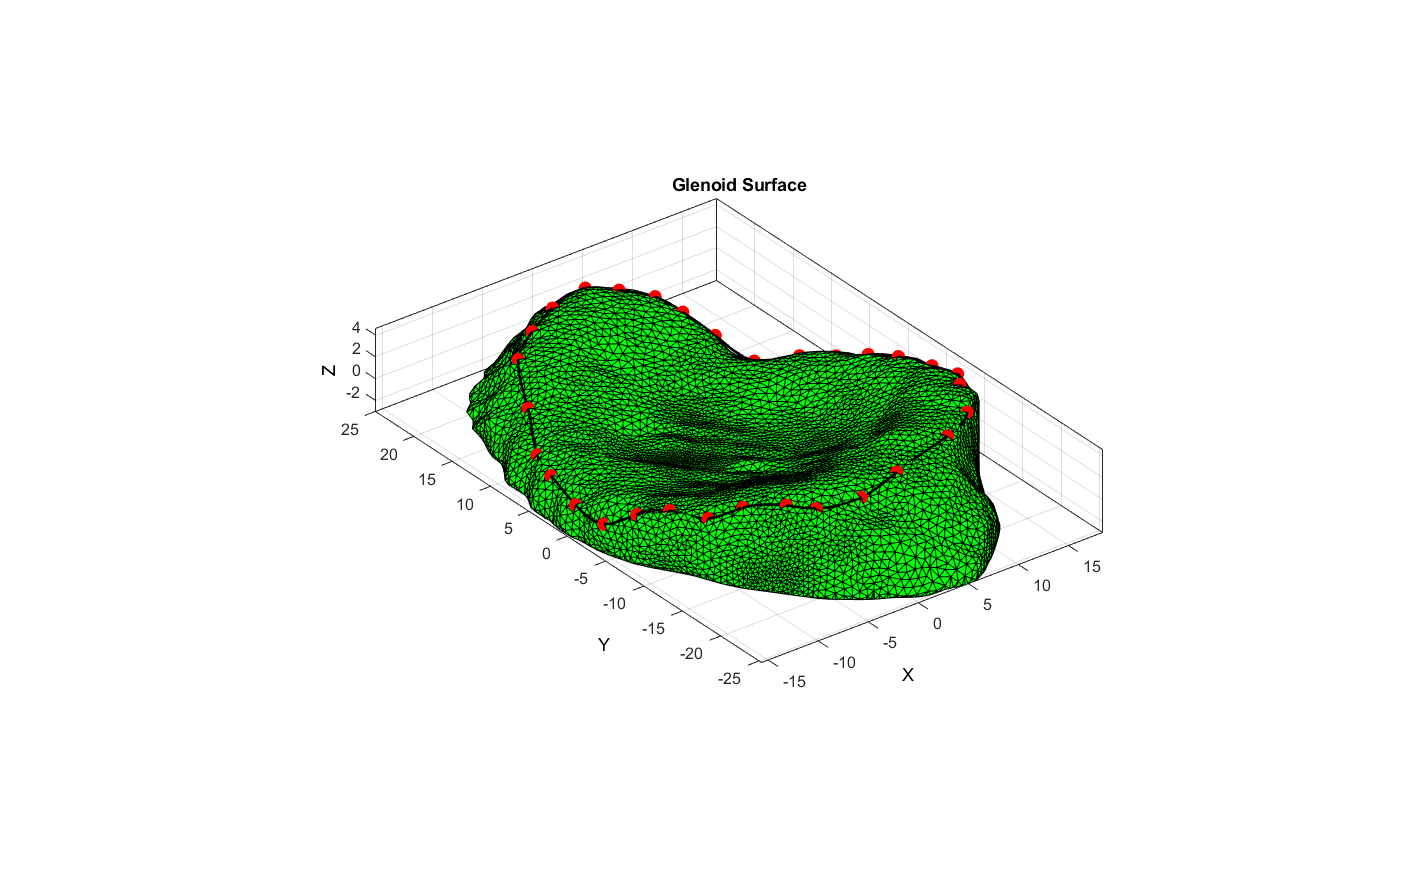

%Place the glenoid rim points into a single structure
%The points need to be placed in an appropriate order so that the smooth
%boundary is fit appropriately. This can be done by finding the angle
%between the origin of the glenoid to the XY points versus vertical, and
%then ordering these.
%For calculating angles, see: https://au.mathworks.com/matlabcentral/answers/486528-how-to-find-angle-between-two-lines
%Calculate angle
for gg = 1:length(glenoidRimLabels)
    if landmarks.(glenoidRimLabels{gg})(1) >= 0 && landmarks.(glenoidRimLabels{gg})(2) >= 0
        ang(gg,1) = atand(landmarks.(glenoidRimLabels{gg})(1)/landmarks.(glenoidRimLabels{gg})(2));
    elseif landmarks.(glenoidRimLabels{gg})(1) >= 0 && landmarks.(glenoidRimLabels{gg})(2) < 0
        ang(gg,1) = atand((landmarks.(glenoidRimLabels{gg})(2)*-1)/landmarks.(glenoidRimLabels{gg})(1)) + 90;
    elseif landmarks.(glenoidRimLabels{gg})(1) < 0 && landmarks.(glenoidRimLabels{gg})(2) < 0
        ang(gg,1) = atand((landmarks.(glenoidRimLabels{gg})(1)*-1)/(landmarks.(glenoidRimLabels{gg})(2)*-1)) + 180;
    elseif landmarks.(glenoidRimLabels{gg})(1) < 0 && landmarks.(glenoidRimLabels{gg})(2) >= 0
        ang(gg,1) = atand(landmarks.(glenoidRimLabels{gg})(2)/(landmarks.(glenoidRimLabels{gg})(1)*-1)) + 270;
    end
    ang(gg,2) = gg;
end
clear gg
%Sort the angles and the indices
sortAng = sortrows(ang,1);
    
%Get the ordered XYZ points of the glenoid rim points
for aa = 1:length(sortAng)
    xyzGlenoidPoints(aa,:) = landmarks.(glenoidRimLabels{sortAng(aa,2)})(1,:);
end
clear aa

%Visualise and get a smoothed boundary
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot glenoid rim points
for gg = 1:length(glenoidRimLabels)
    scatter3(landmarks.(glenoidRimLabels{gg})(1),...
        landmarks.(glenoidRimLabels{gg})(2),...
        landmarks.(glenoidRimLabels{gg})(3),100,'r','filled');
end
%Get and plot smoothed boundary
xyzGlenoidPoints = xyzGlenoidPoints';
smoothedGlenoidBoundary = fnplt(cscvn(xyzGlenoidPoints(:,[1:end 1])),'r',2);
plot3(smoothedGlenoidBoundary(1,:),...
    smoothedGlenoidBoundary(2,:),...
    smoothedGlenoidBoundary(3,:),'k-','LineWidth',2)

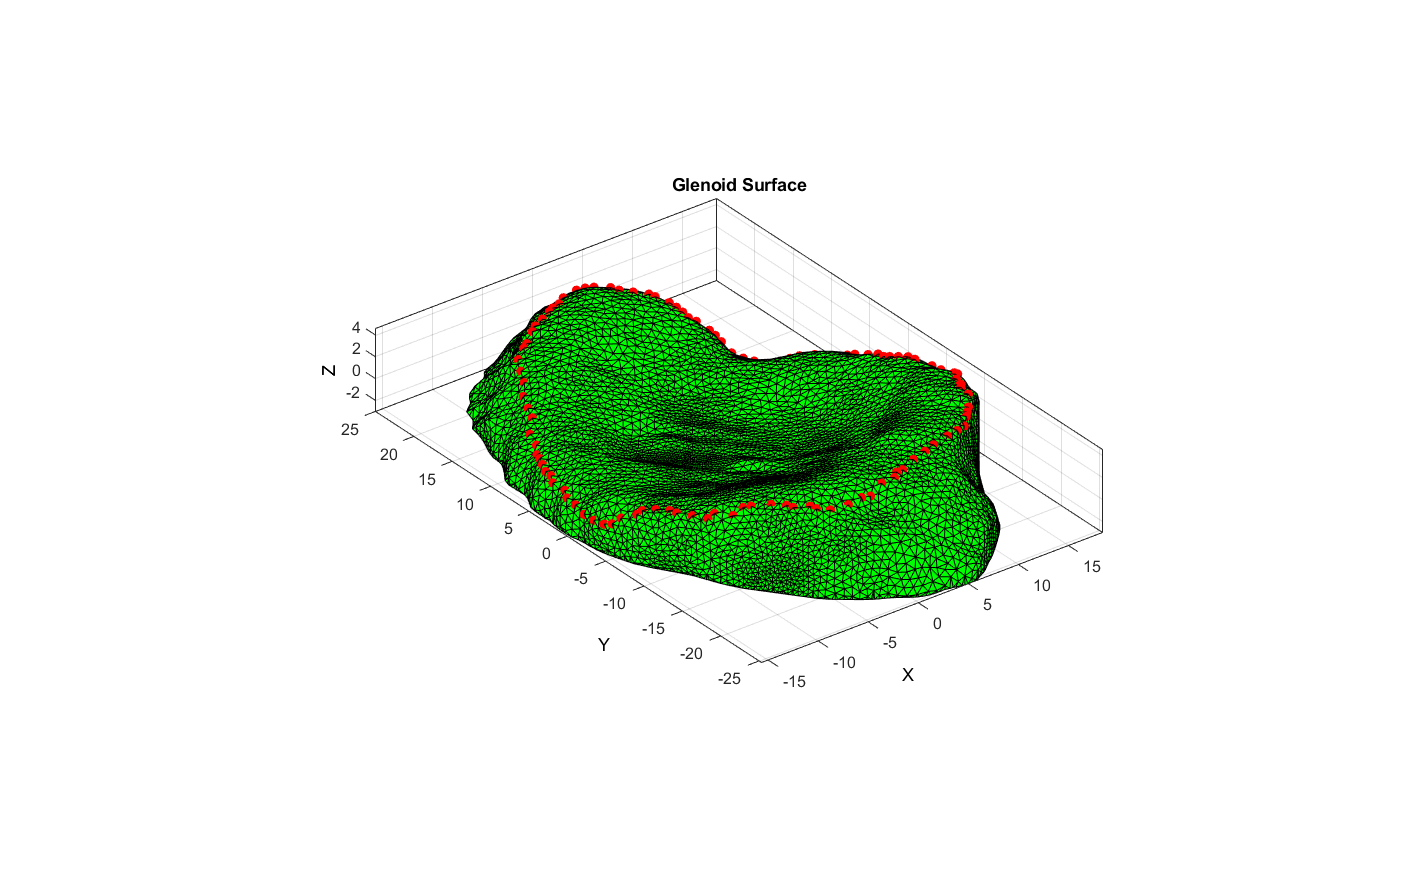

%Transpose the new smoothed points so they are in XYZ form
smoothedGlenoidBoundary = smoothedGlenoidBoundary';

%Re-run the same process as before in identifying the closest vertices to
%the smoothed boundary points to ensure they lie on the glenoid surface
%Calculate nearest vertices to each glenoid rim point
for gg = 1:length(smoothedGlenoidBoundary)

    %Loop through glenoid vertices and calculate distances
    for vv = 1:length(glenoidV)
        %Specify points
        P1 = glenoidV(vv,:); P2 = smoothedGlenoidBoundary(gg,:);
        distPoints(vv) = sqrt((P1(:,1)-P2(:,1)).^2+(P1(:,2)-P2(:,2)).^2+(P1(:,3)-P2(:,3)).^2);
        clear P1 P2
    end
    clear vv
    
    %Find the minimum distance
    minInd = find(distPoints == min(distPoints));
    
    %Replace the current glenoid rim point with the one from the glenoid
    %surface vertices
    smoothedGlenoidBoundary(gg,:) = glenoidV(minInd,:);
    
    %Cleanup
    clear distPoints minInd

end
clear gg

%Replot points to have a look
cFigure; hold on;
title('Glenoid Surface','FontSize',fontSize);
%Plot glenoid surface
gpatch(glenoidF,glenoidV,'g','k',1);
axisGeom(gca,12);
%Plot glenoid rim points
for gg = 1:length(smoothedGlenoidBoundary)
    scatter3(smoothedGlenoidBoundary(gg,1),...
        smoothedGlenoidBoundary(gg,2),...
        smoothedGlenoidBoundary(gg,3),50,'r','filled');
end

## Extend Along the Smoothed Glenoid Boundary

Now that we have a potentially appropriate boundary, we can extend out from the glenoid face to create a cartilage structure. This could be done using the new patchExtend method, or by using the earlier loft feature of the GIBBON toolbox.

Before doing this we need to remove the faces/vertices that sit inside the smoothed boundary region so that the top of the glenoid surface becomes an open edge.

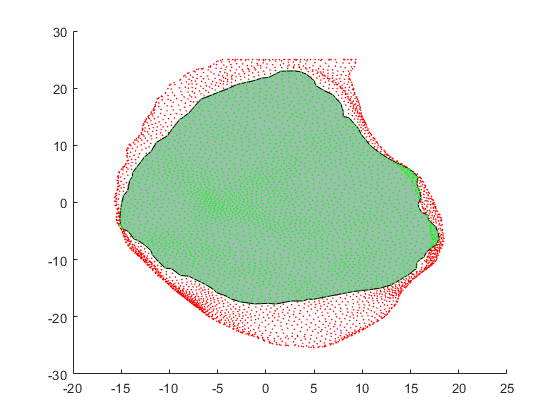

%Create a polyshape based on the smoothed points
polyin = polyshape(smoothedGlenoidBoundary(:,1),smoothedGlenoidBoundary(:,2));

%Plot poly and all points
plot(polyin)
hold on
scatter(glenoidV(:,1),glenoidV(:,2),2,'k','filled')

%Determine which glenoid vertices are within the smoothed boundary
inFace = isinterior(polyin,glenoidV(:,1),glenoidV(:,2));

%Plot those that are in and out with green and red
scatter(glenoidV(inFace,1),glenoidV(inFace,2),2,'g','filled')
scatter(glenoidV(~inFace,1),glenoidV(~inFace,2),2,'r','filled')

%Create a detached mesh set based on whether to keep the vertices or not
logicKeep = all(~inFace(glenoidF),2);
[glenoidEdgeF,glenoidEdgeV] = patchCleanUnused(glenoidF(logicKeep,:),glenoidV);

%Visualise new mesh
cFigure; hold on

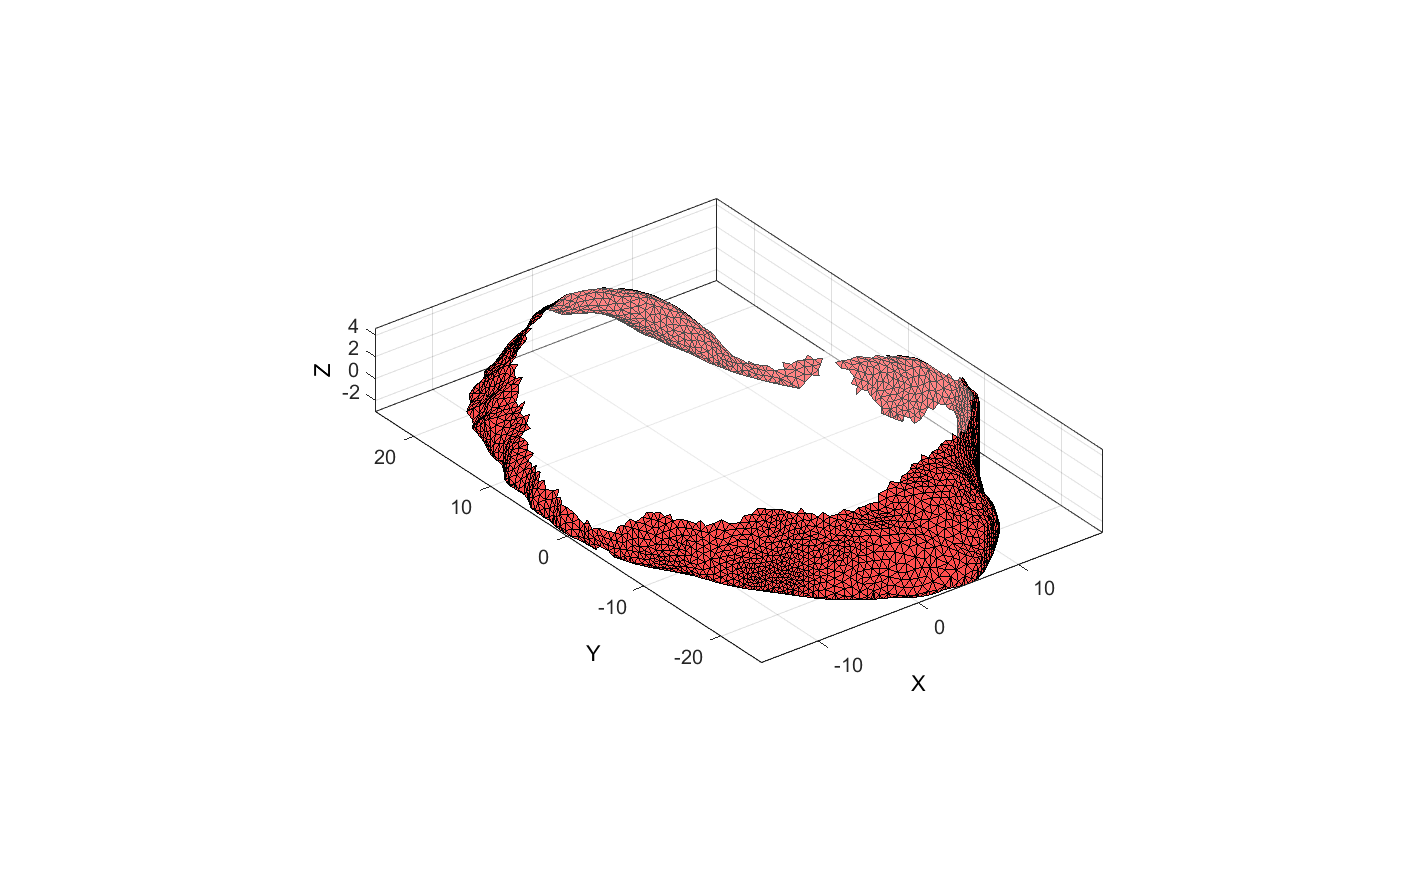

gpatch(glenoidF,glenoidV,'w','none',0.3);
gpatch(glenoidEdgeF,glenoidEdgeV,'r','k',1);
axisGeom;

With this newly edged glenoid we can now examine how a basic method would work extending the edges by 20mm.

%Get the surface and boundary edges 
Eb = patchBoundary(glenoidEdgeF,glenoidEdgeV); %All boundary edges (including bottom)
VE = patchCentre(Eb,glenoidEdgeV); %Edge centre coordinates

%Find the closest point in the edge boundary coordinates to the earlier
%smoothed boundary points on the glenoid face


### UP TO HERE!


logicTop = VE(:,3)>0; %Logic for top edges (Z-coordinate above 0)
Eb = Eb(logicTop,:); %Set of edges at the top

%Set the options
optionStruct.numSteps = [];
optionStruct.plotOn = 1;
optionStruct.meshType = [];
optionStruct.globalDirection = [0,0,1]; %z-direction to extend in
optionStruct.extendDistance = 20; %Extend distance
optionStruct.extendMethod = 1; %Method to use for extruding; equal offset along local direction

%Extend
[cartilageF,cartilageV] = patchExtend(glenoidF,glenoidV,smoothedGlenoidBoundary,optionStruct);


%Set the option struct for patchExtend
optionStruct.numSteps = [];
optionStruct.plotOn = 0;
optionStruct.meshType = [];
optionStruct.globalDirection = [0,0,1]; %z-direction to extend in
optionStruct.extendDistance = 20; %Extend distance


We can then have a look at how the different methods work extending the surface by a standard distance of 20mm.

Do the processes involved with the above manually to get the patches and only plot the normals that we want.

% % % %Get the patch normals
% % % [N,Vn] = patchNormal(scapulaF_slice,scapulaV_slice);   

The likely solution is to identify the normals that have a predominantly positive z-direction component, and subsequently lacking a real X and Y direction component.

% % % %Test plot faces of normals that have a small X and Y normal component
% % % plotNormals = logical(abs(N(:,1)) < 0.1 & logical(abs(N(:,2) < 0.1)))
% % % 
% % % %Visualise
% % % cFigure; hold on;
% % % hp1 = gpatch(scapulaF_slice(plotNormals),scapulaV_slice(scapulaF_slice(plotNormals),'gw','k',1);
% % % hp2 = gpatch(scapulaF_slice(~plotNormals,:),scapulaV_slice(~plotNormals,:),'rw','k',1);
% % % legend([hp1 hp2],{'Selected Normals','Unselected Normals'})
% % % axisGeom; axis manual; camlight headligth;
% % % colormap gjet;
% % % set(gca,'FontSize',fontSize);

***TODO: plotting of selected faces not working - check how this is done in other help functions like the patchNormFix HELP.***

TODO: extract the normals we want.

NOTE: N refers to the normal direction, while Vn refers to the 3d location (I think...). Check the patchNormPlot code for how it can be used. To achieve the goal, effectively we want to identify the normals that are located within a specific boundary (i.e. close to the glenoid) and those that point in a certain direction above a threshold (i.e. upwards/upwards above a specific angle threshold from the glenoid).